%% Analyse av lukket sløyfesystem
% Oppgaven er å analysere systemet:
% G(s) = 75 * (1 + s/10) / (s * (1 + s/2) * (1 + s/40))

%% Initialiser transferfunksjonen G(s)
s = tf('s');
%G = 75 * (1 + s/10) / (s * (1 + s/2) * (1 + s/40));
G = (9.772*(s+160))/((0.125*s+1)^2 * (s+80))

G =
 
           9.772 s + 1564
  ---------------------------------
  0.01562 s^3 + 1.5 s^2 + 21 s + 80
 
Continuous-time transfer function.
Model Properties



%% Identifiser systemtype basert på antall poler i origo
[num, den] = tfdata(G, 'v'); % Hent tellere og nevnere
poles = roots(den); % Finn polene
poles_in_origin = sum(abs(poles) < 1e-6); % Tell poler i origo

if poles_in_origin == 0
    system_type = 'Type 0';
elseif poles_in_origin == 1
    system_type = 'Type 1';
elseif poles_in_origin == 2
    system_type = 'Type 2';
elseif poles_in_origin == 3
    system_type = 'Type 3';
else
    system_type = 'Høyere type';
end

fprintf('Systemtype: %s\n', system_type);

Systemtype: Type 0



%% a.1) Statisk feil for enhetssprang (R(s) = 1/s)
% Beregn lukket-sløyfe-overføringsfunksjonen T(s)
T = G / (1 + G);

% Posisjonsforsterkning Kp
Kp = dcgain(G); % DC-forsterkning (gjelder for enhetssprang)

% Statisk feil e_inf
e_inf = 1 / (1 + Kp);

fprintf('Posisjonsforsterkning (Kp): %.3f\n', Kp);

Posisjonsforsterkning (Kp): 19.544


fprintf('Statisk feil (e_inf): %.3f\n', e_inf);

Statisk feil (e_inf): 0.049



%% a.2) Steady-state-verdi for r(t) = cos(12t)
% Frekvensen omega = 12 rad/s
omega = 12;

% Evaluer T(j*omega)
[mag, phase, omega_out] = bode(T, omega);
mag = squeeze(mag); % Hent ut forsterkningen (magnitude) ved omega = 12

% Steady-state amplitude
steady_state_amplitude = mag;

fprintf('Steady-state amplitude ved omega = %.1f rad/s: %.3f\n', omega, steady_state_amplitude);

Steady-state amplitude ved omega = 12.0 rad/s: 1.068


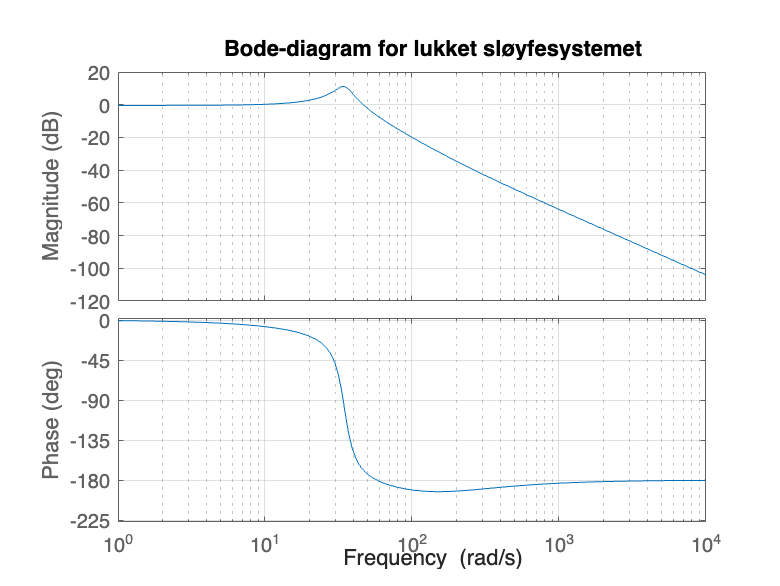


%% Visualisering av Bode-diagrammet
figure;
bode(T);
grid on;
title('Bode-diagram for lukket sløyfesystemet');